clear
clc
a = csvread('thickness2rgb2.csv');
x = a(:,2);
ry = a(:,3);
gy = a(:,4);
by = a(:,5);
rp = fit(x,ry,'sin3');
gp = fit(x,gy,'sin3');
bp = fit(x,by,'sin3');

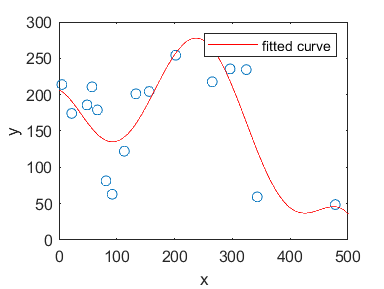

figure
plot(x,ry,'o')
hold on
plot(rp)
hold off

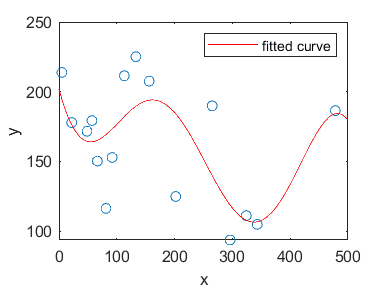

figure
plot(x,gy,'o')
hold on
plot(gp)
hold off

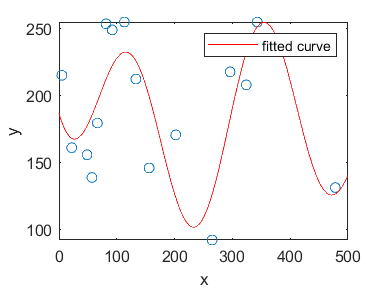

figure
plot(x,by,'o')
hold on
plot(bp)
hold off

rgbmatrix = zeros(3,500,'double');
for i = 1:500
    rgbmatrix(1,i) = rp(i);
    rgbmatrix(2,i) = gp(i);
    rgbmatrix(3,i) = bp(i);
end

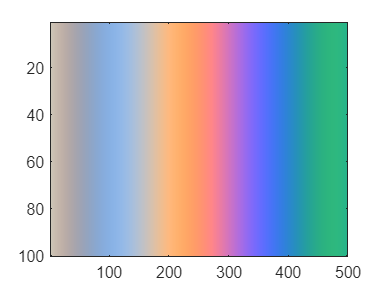

r = rgbmatrix(1,:);
g = rgbmatrix(2,:);
b = rgbmatrix(3,:);
C(:,:,1) = r.*ones(100,1)/256;
C(:,:,2) = g.*ones(100,1)/256;
C(:,:,3) = b.*ones(100,1)/256;
image(C)

save('rm.mat',"rgbmatrix")